# ECE1150 ASSIGNMENT4

Yinhao Qian @ University of Pittsburgh

%please ignore this block
answer = @(num,unit) fprintf(" ANSWER: %s [%s]" + ...
    " \n",mat2str(num),unit);
question = @() eval("clearvars -except answer question");

# Q1A

question();
A = 2;%[] amplitude
f = (48*pi)/(2*pi);%[Hz] frequency
phi = 0;%[] phase
samplingRate = 2*f;%[Hz] minimum sampling rate
answer(samplingRate,"Hz");

 ANSWER: 48 [Hz] 


# Q1B

I assume this question is asking the quantization sequence rather than the quantization levels, as the quantiztion levels are given.

H = 2;%[] max cap
L = -2;%[] min cap
N = 8;%[] quatization levels

Size of quantization intervals:

S = (H-L)/N;%[] size of quantization intervals
answer(S,"");

 ANSWER: 0.5 [] 


Sequence of quantization intervals:

sequence = -2+S:S:2-S;
answer(sequence,"")

 ANSWER: [-1.5 -1 -0.5 0 0.5 1 1.5] [] 


# Q1C

maxError = S/2;%[] maximum quantization error
answer(maxError,"");

 ANSWER: 0.25 [] 


# Q1D

b = log2(N);%[] bits needed to represent each quantization level
answer(b,"");

 ANSWER: 3 [] 


# Q1E

sampledValue = 1.1;%[] sampled value
index = find(sequence>sampledValue,1)-1;%[] 0-based index
binaryCode = dec2bin(index);%[] binary code
answer(binaryCode,"")

 ANSWER: '110' [] 


# Q1F

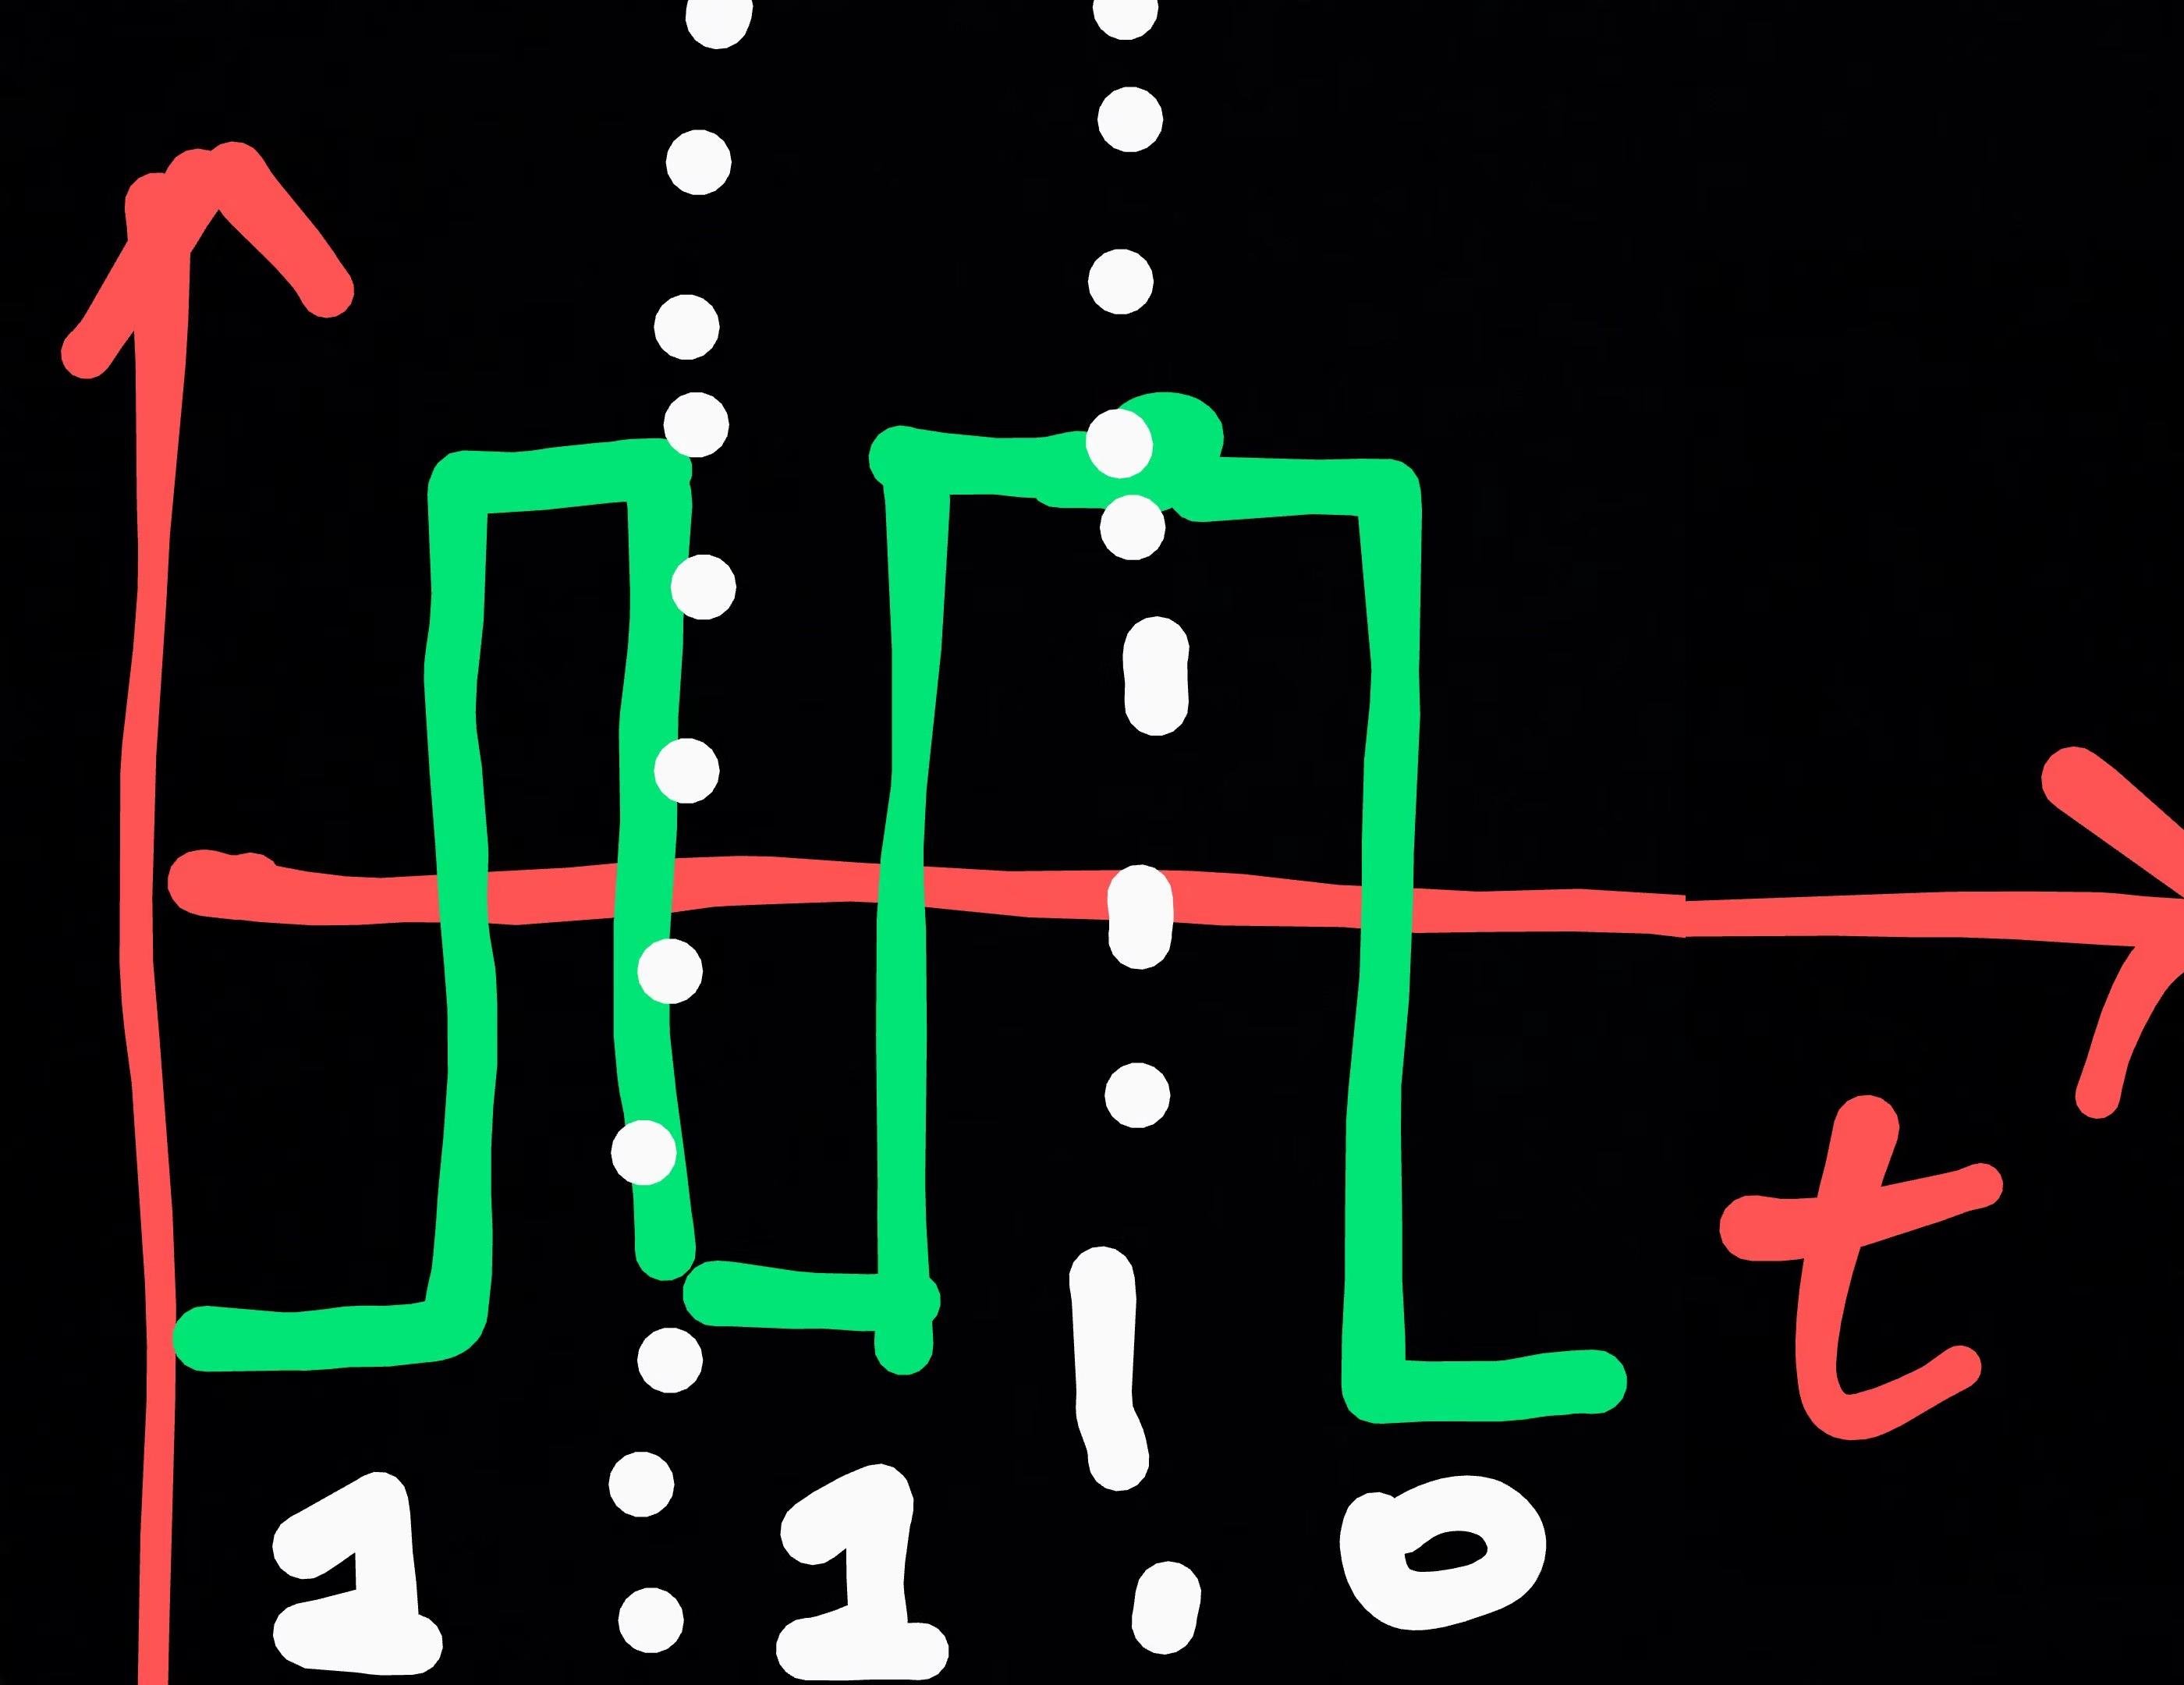

# Q2A

I'm not sure if the topics of QAM and multiplexing is completed covered by the due day of this homework, but I'll try my best to answer this question.

question();
maxSymbolRate = 5e9;%[symbols/s]
answer(maxSymbolRate,"symbols/s");

 ANSWER: 5000000000 [symbols/s] 


# Q2B

k = 2;
baud = maxSymbolRate*k;
answer(baud,"bits/s");

 ANSWER: 10000000000 [bits/s] 


# Q2C

k = 4;
baud = maxSymbolRate*k;
answer(baud,"bits/s");

 ANSWER: 20000000000 [bits/s] 


%please ignore this block
export("submission.mlx","submission.tex");